% Define the data for lower limit, upper limit, and frequency
lowerLimits = [0,40,80,120,160,200,240,280,320,360,400]; 
upperLimits = [40,80,120,160,200,240,280,320,360,400,440]; 
frequencies = [100,79,86,93,65,75,54,43,32,12,1];  

% Create a table in MATLAB
dataTable = table(lowerLimits', upperLimits', frequencies',...
    'VariableNames', {'LowerLimit', 'UpperLimit', 'Frequency'});

% Display the table
disp(dataTable);

    LowerLimit    UpperLimit    Frequency
    __________    __________    _________

         0            40           100   
        40            80            79   
        80           120            86   
       120           160            93   
       160           200            65   
       200           240            75   
       240           280            54   
       280           320            43   
       320           360            32   
       360           400            12   
       400           440             1   




% Calculate mean, median, mode, and standard deviation
data = [];
for i = 1:length(lowerLimits)
    data = [data, ones(1, frequencies(i)) * ((upperLimits(i) + lowerLimits(i)) / 2)];
end

meanValue = mean(data);
medianValue = median(data);
modeValue = mode(data);
stdDeviation = std(data);

% Calculate empirical_mode, mode_shift, and Karl
empirical_mode = 3 * medianValue - 2 * meanValue;
mode_shift = modeValue - empirical_mode;
Karl = (meanValue - modeValue) / stdDeviation;

% Display the calculated statistics
fprintf('Mean: %.2f\n', meanValue);

Mean: 155.25


fprintf('Median: %.2f\n', medianValue);

Median: 140.00


fprintf('Mode: %.2f\n', modeValue);

Mode: 20.00


fprintf('Standard Deviation: %.2f\n', stdDeviation);

Standard Deviation: 100.44


fprintf('Empirical Mode: %.2f\n', empirical_mode);

Empirical Mode: 109.50


fprintf('Mode Shift: %.2f\n', mode_shift);

Mode Shift: -89.50


fprintf('Karl: %.2f\n', Karl);

Karl: 1.35


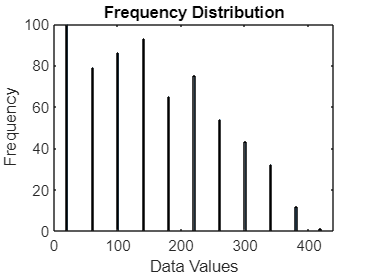


% Plotting the line graph
figure;
histogram(data, 'BinWidth', 2); % Change the 'BinWidth' according to your preference
title('Frequency Distribution');
xlabel('Data Values');
ylabel('Frequency');